# Verificação da transformada

## Boas práticas

Configuramos as principais tarefas de limpeza

clear all;          % limpa as variáveis
clc;                % limpa a tela
close all;          % fecha as janelas           

## Definir a transformada

X = @(n)   1.2*sinc(n*2*0.8/2)   % transformada

X = function_handle with value:
    @(n)1.2*sinc(n*2*0.8/2)



%     sinc(X) returns a matrix whose elements are the sinc of the elements 
%     of X, i.e.
%          y = sin(pi*x)/(pi*x)    if x ~= 0
%            = 1                   if x == 0

## Calcular a transformada

$D_n = \frac{X(n \omega_o)}{T_o}$          , vamos verificar a série associada

N  = 10;         % número de harmônicas
n  = [-N:1:N];   % n
To = 1;          % período
wo = 2*pi/To;    % frequência angular

w  = n*wo;        % harmônicas de Fourier
f = w/(2*pi);     % em Hertz

Dn = X(n);        % série de Fourier


## Visualizar a transformada﻿

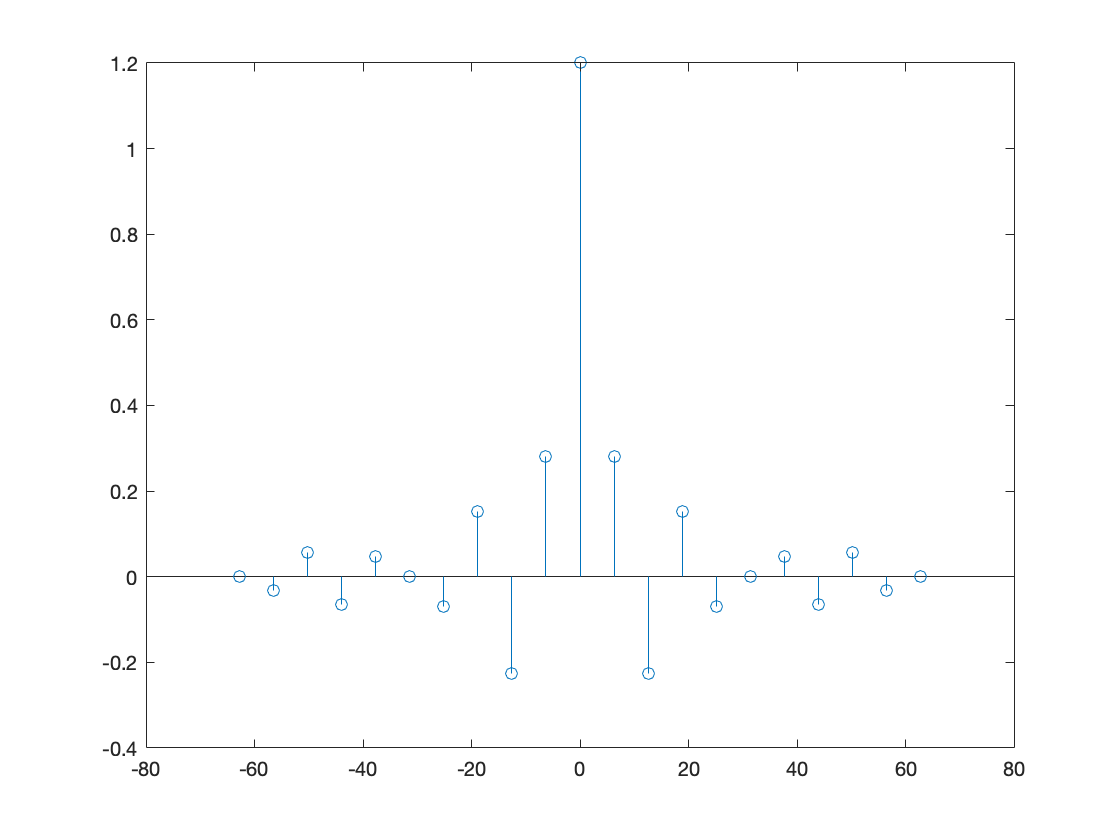

figure(1)
stem(w,Dn)

## Sintetizar o sinal

M = 1000;           % número de pontos da síntese
Ts = To/M;          % resolução do sinal
tempo = [-To:Ts:To]; % variável tempo

aux = 0;            % inciando a somatória

for k=0:2*N
    
    aux = aux + Dn(k+1)*exp(j*n(k+1)*wo*tempo);
end

sinal = aux;

## Visualizar o sinal

figure(2)
plot(tempo,sinal);

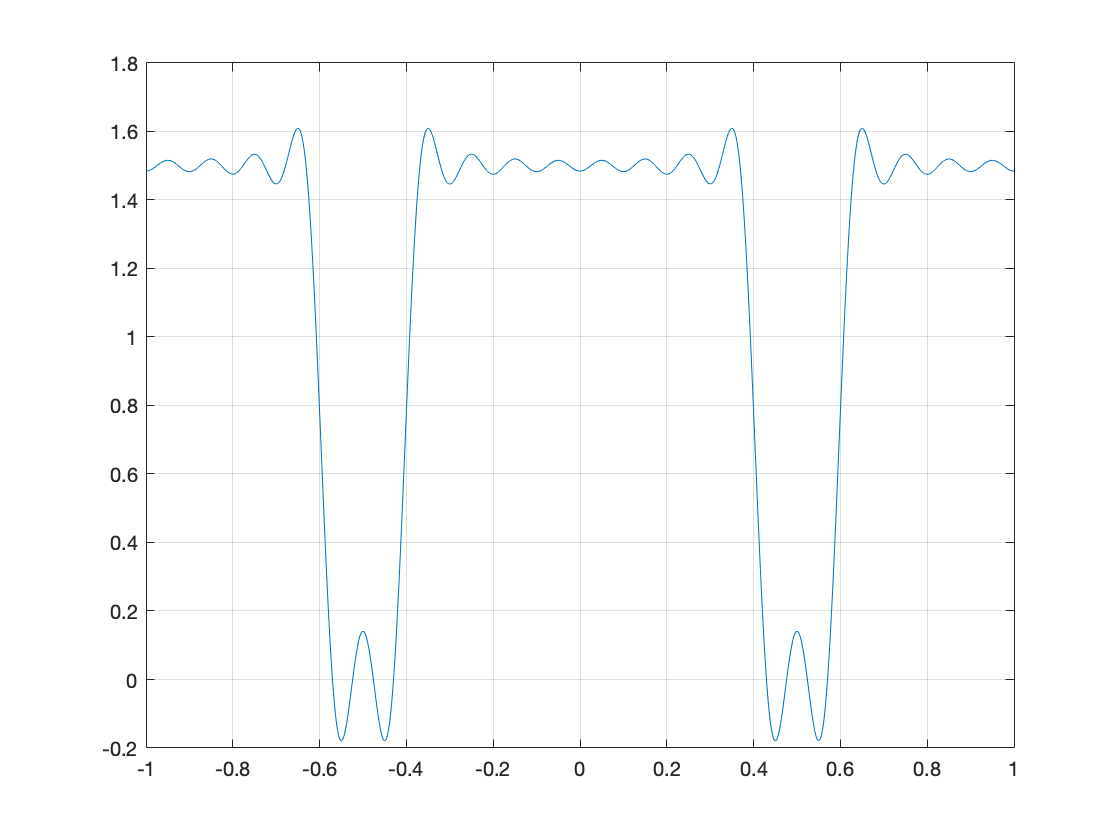

grid;